creativity = 0:0.1:1;
comp_mission = [24955, 24942, 24827, 24657, 24396, 23981, 23533, 22937, 22293, 22109, 22140];
fail_mission = [45, 58, 173, 343, 604, 1019, 1467, 2063, 2707, 2891, 2860];

Calculate the success and fail percentage of each creativity state.

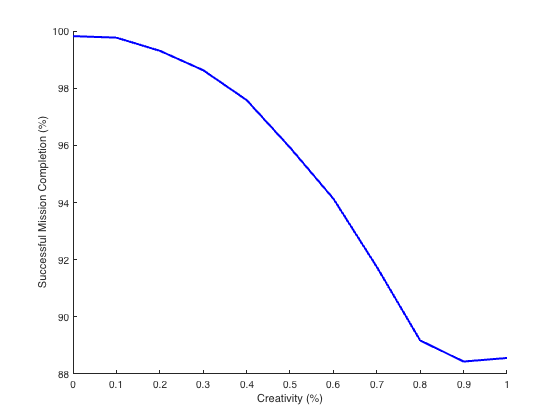

pct_succ = zeros(1, size(comp_mission, 1));
pct_fail = zeros(1, size(comp_mission, 1));
for i = 1:1:size(comp_mission, 2)
    pct_succ(1, i) = (comp_mission(1, i) / (comp_mission(1, i) + fail_mission(1, i))) * 100;
    pct_fail(1, i) = (fail_mission(1, i) / (comp_mission(1, i) + fail_mission(1, i))) * 100;
end

figure(1)
hold on 
plot(creativity, pct_succ, 'color', 'b', 'linewidth', 2);
ylabel('Successful Mission Completion (%)')
xlabel('Creativity (%)')

When performing a simulation, the robot can request the human to redirect from it's current location to a safe location. When the robot does so, this is logged for analysis as to understand how often the robot requests a redirect, and how successful the redirect is based on the human's creativity levels.

redirects = [1, 2, 3, 4, 5, 6, 7, 8];
total = [11369, 12799, 13193, 13391, 13113, 12672, 12080, 11138, 9863, 8338, 6077];

success = [
    10241,  883,    153,    46,     1,      0,      0,      0;      % Creativity value = 0.0
    9760,   2446,   460,    68,     7,      0,      0,      0;      % Creativity value = 0.1
    9537,   2721,   663,    114,    15,     0,      0,      0;      % Creativity value = 0.2
    9374,   2967,   591,    102,    13,     1,      0,      0;      % Creativity value = 0.3
    9095,   2737,   571,    91,     14,     1,      0,      0;      % Creativity value = 0.4
    8618,   2426,   481,    65,     17,     1,      0,      0;      % Creativity value = 0.5
    8277,   1954,   340,    37,     5,      0,      0,      0;      % Creativity value = 0.6
    7462,   1424,   178,    10,     1,      0,      0,      0;      % Creativity value = 0.7
    6289,   808,    58,     1,      0,      0,      0,      0;      % Creativity value = 0.8
    5130,   312,    5,      0,      0,      0,      0,      0;      % Creativity value = 0.9
    3127,   0,      0,      0,      0,      0,      0,      0;      % Creativity value = 1.0
];

failed = [
    0,      0,      1,      14,     30,     0,      0,      0;      % Creativity value = 0.0
    5,      12,     30,     10,     1,      0,      0,      0;      % Creativity value = 0.1
    38,     73,     41,     17,     3,      1,      0,      0;      % Creativity value = 0.2      
    84,     150,    76,     22,     8,      2,      1,      0;      % Creativity value = 0.3      
    244,    255,    89,     13,     2,      1,      0,      0;      % Creativity value = 0.4      
    509,    377,    122,    10,     1,      0,      0,      0;      % Creativity value = 0.5      
    936,    408,    108,    15,     0,      0,      0,      0;      % Creativity value = 0.6      
    1565,   443,    48,     7,      0,      0,      0,      0;      % Creativity value = 0.7      
    2290,   382,    31,     4,      0,      0,      0,      0;      % Creativity value = 0.8      
    2685,   197,    9,      0,      0,      0,      0,      0;      % Creativity value = 0.9
    2860,   0,      0,      0,      0,      0,      0,      0;      % Creativity value = 1.0
];